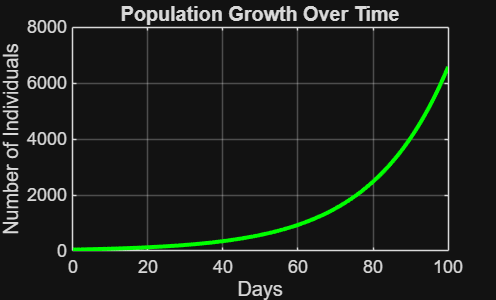

%% Population Growth Simulation
clear; clc; %clears the memory                                    

% Constraints
P0 = 50; % initial population, the starting number of people/bacteria
r = 0.05; %growth rate (5%), how fast they reproduce
dt = 1; %time step (1 day), each loop represents one day
max_days = 100; %total time, how long to run the simulation

% Initial conditions 
t = 0; %start at day 0 (Initial time)
P = P0; %set current population (Start with initial count)

t_history = []; %list for time days to keep track for the graph
P_history = []; %list for population count so you can keep track for the graph

% Simulation loop
while t <= max_days
    % Save current data before changing it
    t_history(end+1) = t;% Record current day
    P_history(end+1) = P;% Record current population
    
    % Calculate Growth
    % Change = Rate * Current Population
    growth = r * P;% Calculate how many new individuals
    P = P + growth;% Add new individuals to total
    % Advance Time
    t = t + dt;% Move to the next day
    
end

% Plotting the results 
plot(t_history, P_history, 'g', 'LineWidth', 2);% Plot population in green
title('Population Growth Over Time');% Add a title
xlabel('Days');% Label the X-axis
ylabel('Number of Individuals');% Label the Y-axis
grid on;% Show the grid